clear
clc
close all

[XTrain,YTrain] = japaneseVowelsTrainData;
[XValidation,YValidation] = japaneseVowelsTestData;

XTrain(1 :5)

ans = 5×1 cell array
    {12×20 double}
    {12×26 double}
    {12×22 double}
    {12×20 double}
    {12×21 double}


numFeatures = 12;
numHiddenUnits = 100;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

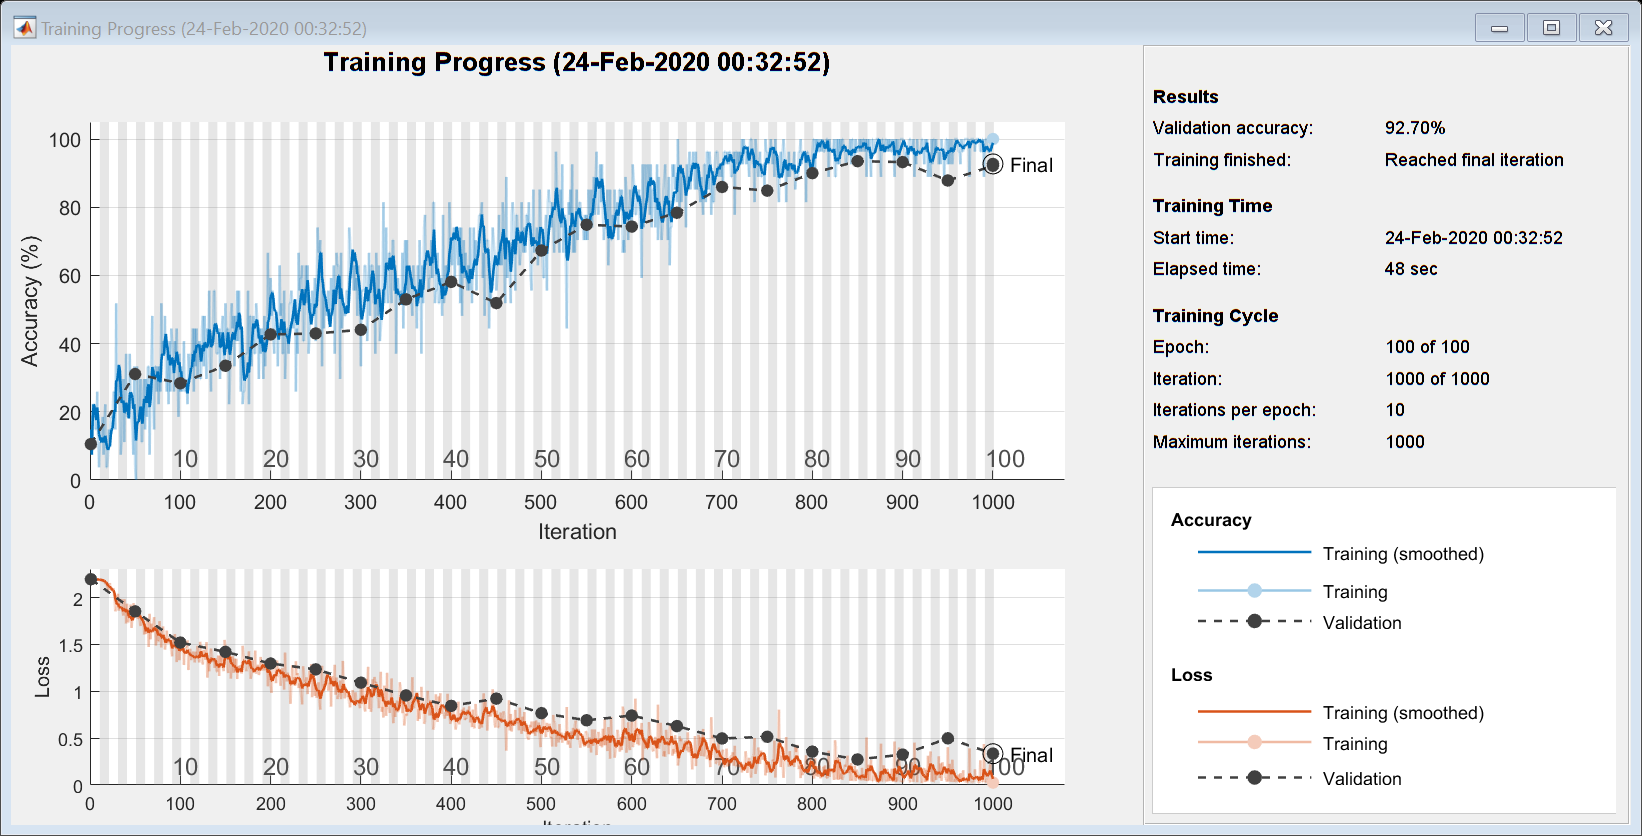

miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',100, ...
    'MiniBatchSize',miniBatchSize, ...
    'ValidationData',{XValidation,YValidation}, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);   

## Test

YPred = classify(net,XValidation,'MiniBatchSize',miniBatchSize);
acc = mean(YPred == YValidation)

acc = 0.9243